## Singular value decomposition (SVD) and eigendecomposition.

## What is the connection between the singular values of X and the eigenvalues of C? What is the connection between the left-singular vectors of X and the eigenvectors of C? Make sure to describe the reasoning behind your answers, e.g., by describing the singular or eigendecompositions of each matrix.

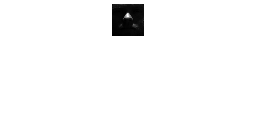

imshow(M(:,:,4)/255)

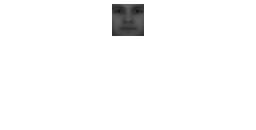

J = reshape(M,[1024,N]); %each column has 1024 entry, each column is a flattened image 
average_face = reshape((mean(J.')),[32,32]);
imshow(average_face(:,:)/255)

X = J - mean(J.').';
C = (X*X.')./N;

The relation between the singular value σ of X and the eigenvalue λ of C is : σ = (sqrt(λ))/N

The relation between the left singular vector u and the eigenvector v is : A.' u = v

By definition, the singular value σ is the squareroot of the eigenvalue λ of AA.' ; left singular vector U is the eigenvector of matrix AA.' , using the property of eigenvector we know Av = λv, compare with AA.' u = λ u, we see that A.' u = v

## Compute the eigenvalue/eigenvector pairs of C and arrange them in decreasing order of the magnitude of the eigenvalues. Let the jth pair in the ordered set be denoted as  j 2 R; v(j) 2 Rd for j 2 [d]. You may  nd the MATLAB command svd or eig helpful. Comment whether the eigenvalues are real and briefly explain why. Plot log  j against j 2 [d]. Include your plot in your solution.

[vect,val]= eig(C)

vect =    -0.0046    0.0036   -0.0131   -0.0024    0.0143    0.0121   -0.0048   -0.0012    0.0115    0.0095    0.0101   -0.0106   -0.0105    0.0148    0.0005   -0.0218    0.0188    0.0023    0.0159    0.0140   -0.0288   -0.0129   -0.0016   -0.0146    0.0138   -0.0170   -0.0214   -0.0095   -0.0079    0.0041    0.0057    0.0269    0.0088   -0.0051   -0.0180    0.0173    0.0366   -0.0147   -0.0100    0.0075   -0.0070    0.0075    0.0107   -0.0153   -0.0093   -0.0093    0.0009   -0.0211    0.0317    0.0086
    0.0124   -0.0183    0.0203    0.0017   -0.0048    0.0103   -0.0018   -0.0036   -0.0245   -0.0337   -0.0143    0.0083    0.0141    0.0025    0.0247   -0.0001    0.0036   -0.0158   -0.0354   -0.0167    0.0217    0.0073   -0.0005    0.0026   -0.0077    0.0198    0.0383    0.0200    0.0175   -0.0213   -0.0013   -0.0449    0.0026    0.0003   -0.0013   -0.0116   -0.0452    0.0076    0.0131   -0.0147   -0.0013   -0.0003   -0.0186    0.0249    0.0142    0.0073    0.0024    0.0259   -0.0367  

val = 	1.0e+06 *

    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

[val_vector, ind] = sort(diag(val), 'descend')

val_vector = 	1.0e+06 *

    1.3686
    1.3406
    0.1853
    0.1076
    0.0584
    0.0537
    0.0400
    0.0355
    0.0276
    0.0255


ind =         1024
        1023
        1022
        1021
        1020
        1019
        1018
        1017
        1016
        1015


val = val(ind,ind)

val = 	1.0e+06 *

    1.3686         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.3406         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

vect = vect(:,ind)

vect =     0.0130    0.0432    0.0129   -0.0753   -0.0396   -0.0243   -0.0796   -0.0188   -0.0186   -0.0532    0.0184   -0.0170    0.0062   -0.0484   -0.0355    0.0016    0.0447   -0.0276   -0.0194   -0.0437   -0.0455    0.0130   -0.0050   -0.0364    0.0060   -0.0351    0.0001    0.0074   -0.0623    0.0140   -0.0650    0.0626    0.0505   -0.0327    0.0632   -0.0168   -0.0100    0.0344    0.0341   -0.0488   -0.0104    0.0017    0.0122   -0.0404   -0.0095    0.0179   -0.0102    0.0276    0.0441    0.0061
    0.0118    0.0434    0.0098   -0.0746   -0.0409   -0.0270   -0.0892   -0.0162   -0.0076   -0.0465    0.0213   -0.0134    0.0182   -0.0405   -0.0281   -0.0022    0.0437   -0.0213   -0.0338   -0.0202   -0.0378    0.0080    0.0143   -0.0392    0.0137   -0.0438    0.0084    0.0184   -0.0669    0.0138   -0.0953    0.0672    0.0477   -0.0263    0.0417   -0.0216    0.0017    0.0427    0.0309   -0.0540    0.0036    0.0095    0.0156   -0.0580   -0.0063    0.0197   -0.0197    0.0225    0.0424  

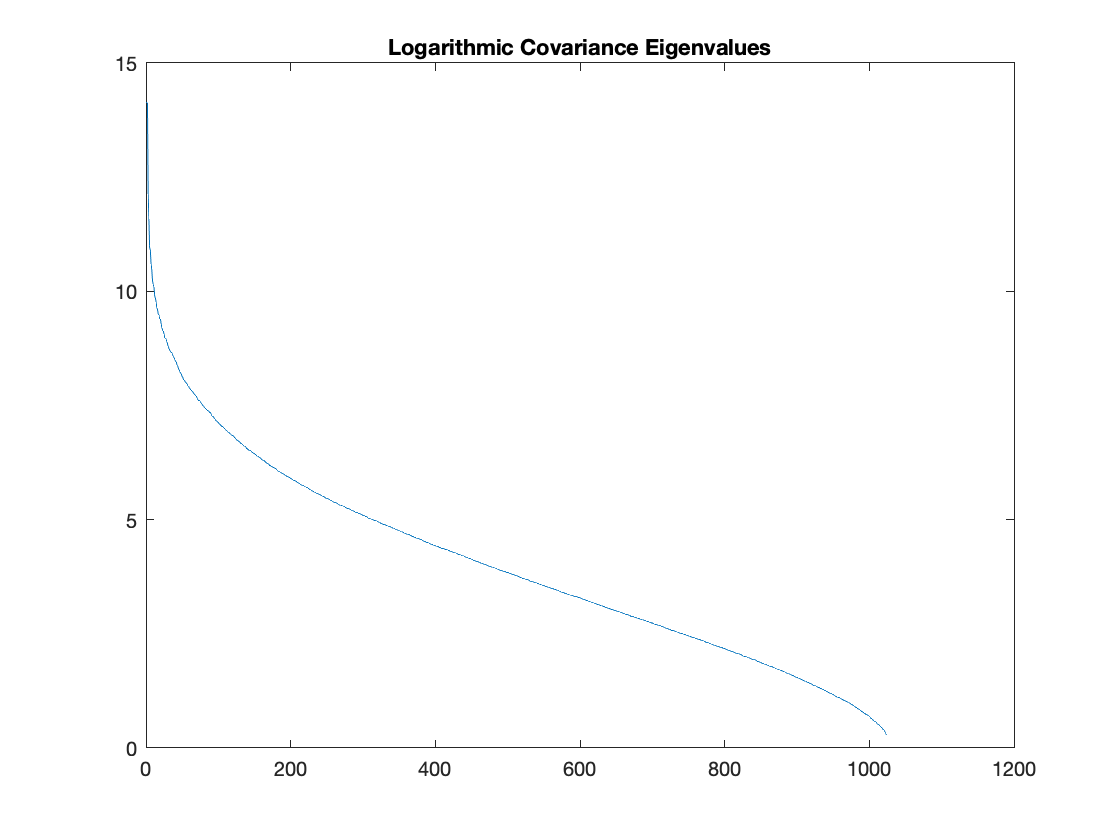

figure 
plot (log(val_vector))
title("Logarithmic Covariance Eigenvalues")

## The set of eigenvectors you computed in the previous part form a basis for the centered image vectors. Reshape each eigenvector v(j) to obtain a 32   32 matrix. These matrices can be considered as images and they are known as eigenfaces. Include plots of two sets of eigenfaces, those corresponding to the largest 10, and those corresponding to the smallest 10, eigenvalues. Do you observe any di erence between the two sets of eigenfaces you plotted? If so briefly explain the reason for this di erence.

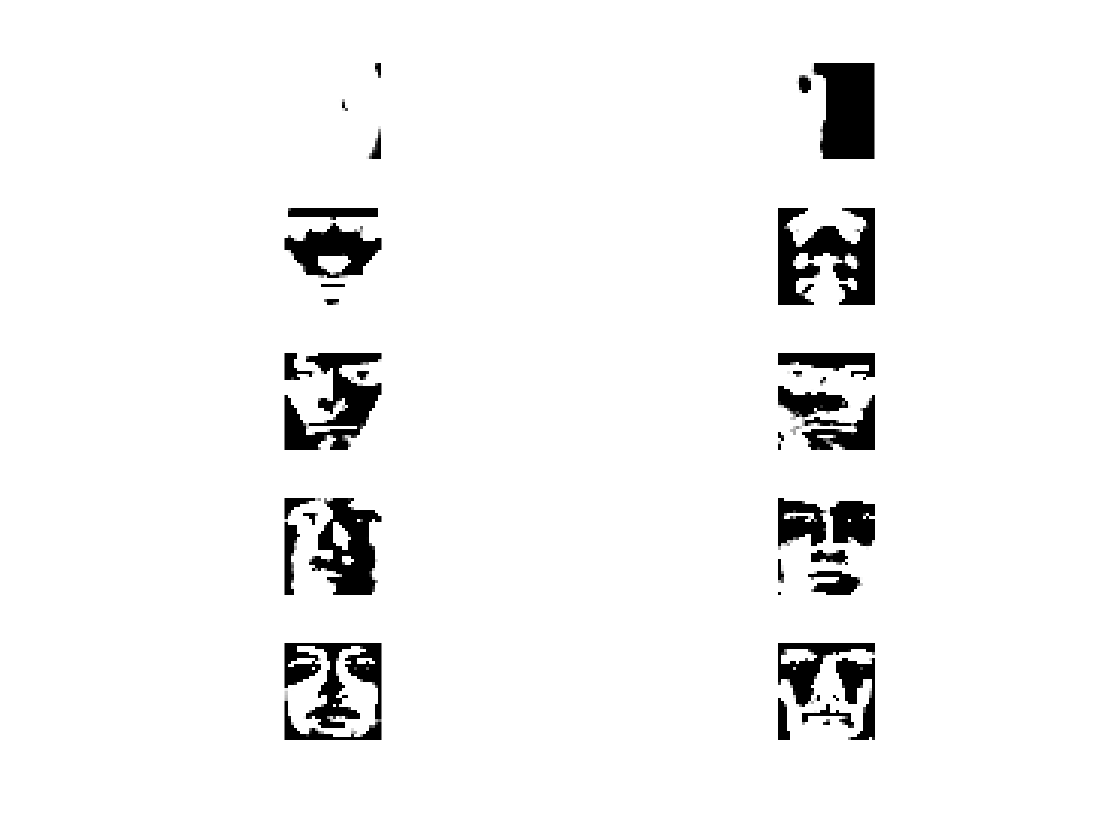

eigenface_mat = reshape(vect,[32,32,1024]);
figure 
for i = 1:10
    subplot(5,2,i),imshow(eigenface_mat(:,:,i).*255)
end

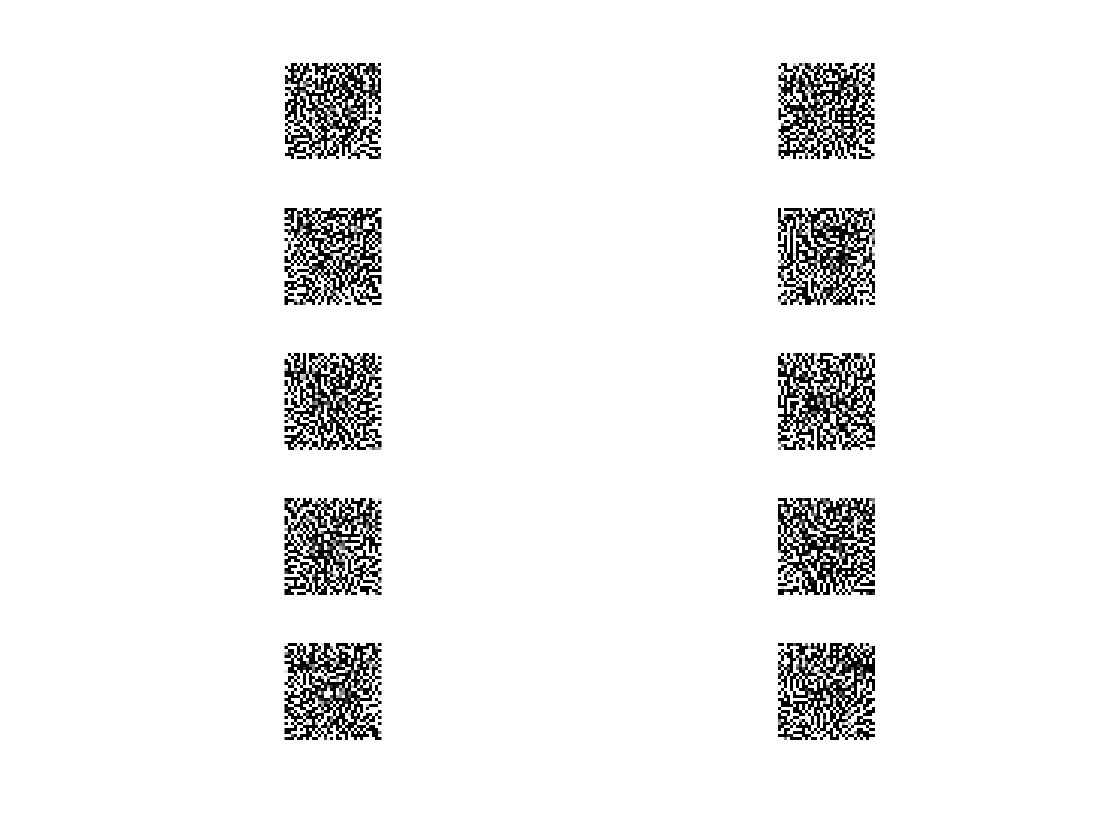

Index in position 2 exceeds array bounds (must not exceed 1).


figure

for i = 1:10
    subplot(5,2,i),imshow(eigenface_mat(:,:,i+1014).*255)
end